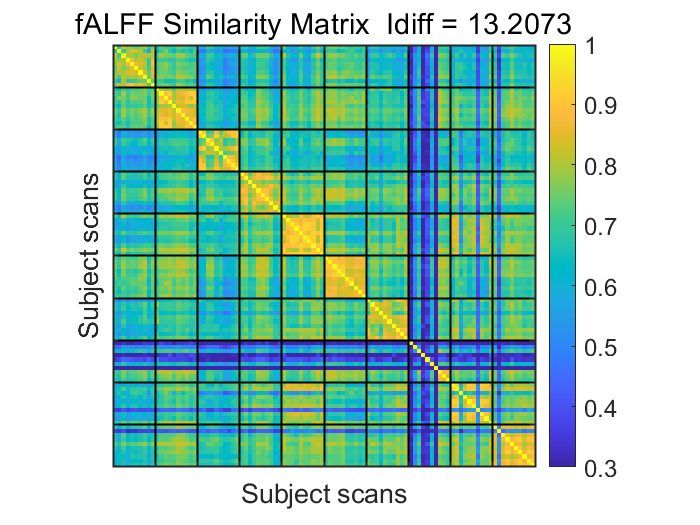

% Read the subject-subject correlation matrix and visualize it

sm_fc=load('./Experimental_Results/FC_ICBM_WM_08HZ.mat').simimat;
GlobalFunctionalVariability(sm_fc);

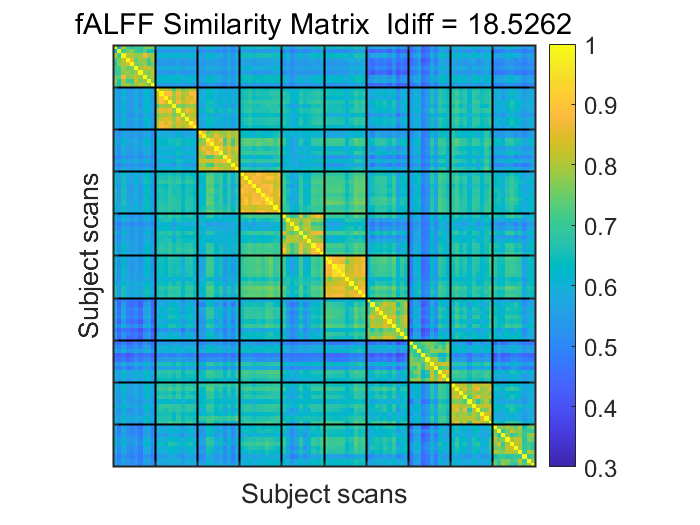

sm_wm=load('./Experimental_Results/TPM_WM_08HZ.mat').simimat;
GlobalFunctionalVariability(sm_wm);

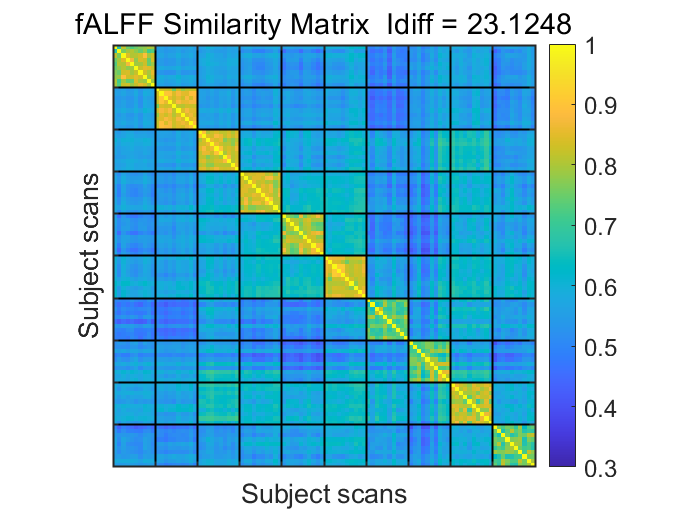

sm_gm=load('./Experimental_Results/TPM_GM_08HZ.mat').simimat;
GlobalFunctionalVariability(sm_gm);

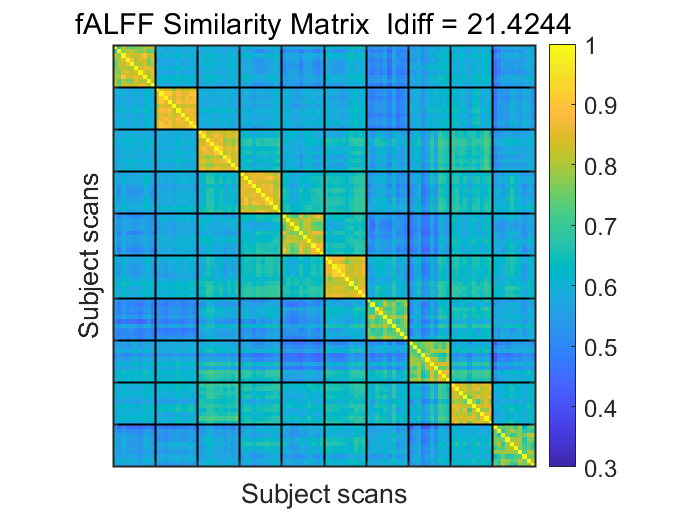

sm_wm_gm=load('./Experimental_Results/TPM_WMandGM_08HZ.mat').simimat;
GlobalFunctionalVariability(sm_wm_gm);

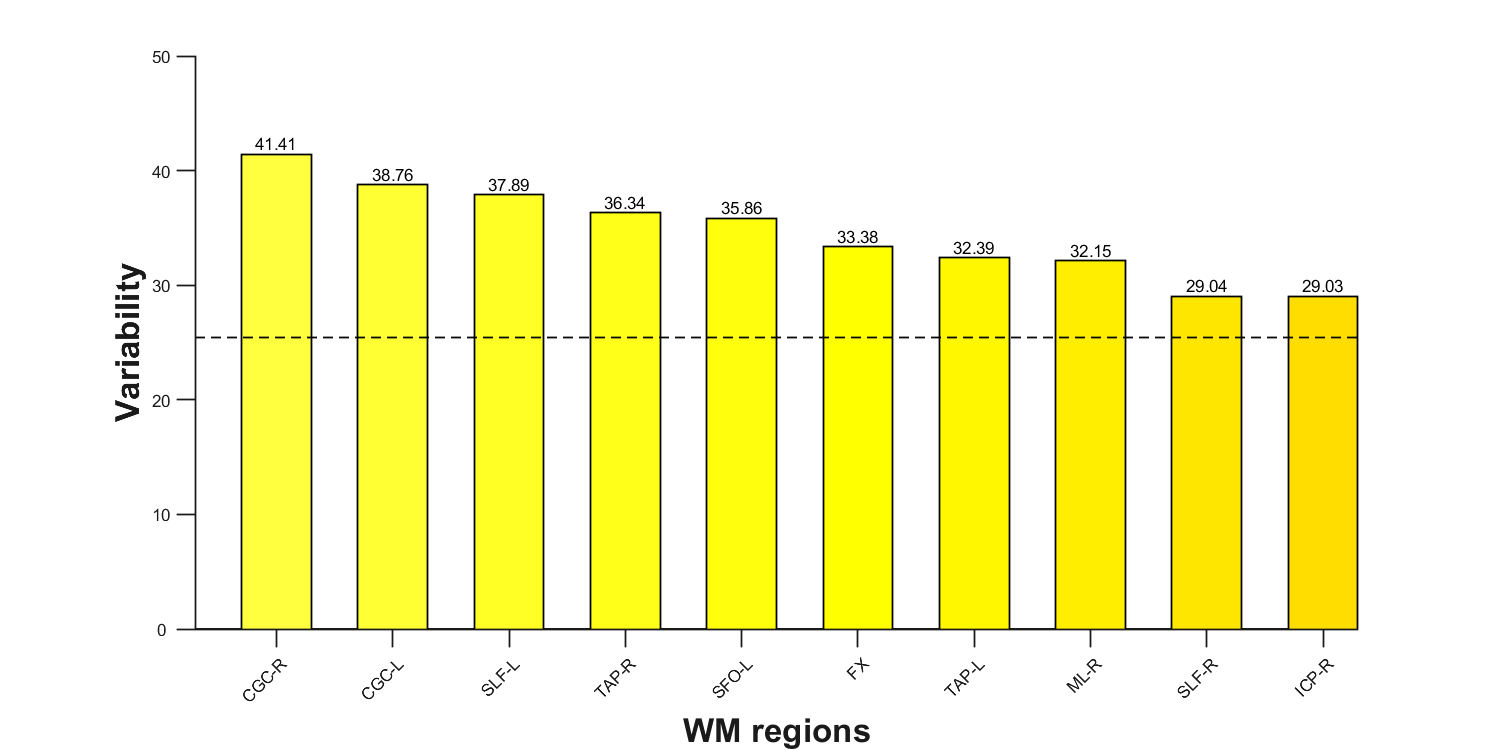

%Read the Idiff of the first 50 ROIs, read the name of each ROI according to the serial number and use it as the Label of the X-axis, and list the first 10 and last 10 ROI bar graphs respectively.
% n means the top n or last n WM regions. You can get Idiff of all WM regions by turning it to 50. 
n=10;
roi50_info=load('./Experimental_Results/ICBM_DTI_81_ROIS/idiff_arr.mat').idiff_arr;
roi50_wholelabel=importdata('./Experimental_Results\LabelLookupTable.txt');
roilabel=cell(1,50);
for i=1:50
    subinfo=split(roi50_wholelabel{i},'	');
    roilabel{i}=subinfo{2};%Read 50 ROI name abbreviations
end
%Get the index of the first n ROIs with the largest idiff
[v_sorted, idx_sorted] = sort(roi50_info, 'descend');

idx_top_n = idx_sorted(1:n);
%Idiff and label of the first n roi
top_n=roi50_info(idx_top_n);
top_n_label=roilabel(idx_top_n);


%Divide the jet into 50 colors, one for each brain region
% map=jet(50);
original_hot=hot(80);
map = flipud(original_hot(16:65,:));
x=1:n;
idffs=bar(x,top_n,'BarWidth',0.6,'EdgeColor',"k","LineWidth",1);
idffs.FaceColor='flat';
for i=1:n
%     idffs.CData(i,:)=map(idx_top_n(i),:);
    idffs.CData(i,:)=map(i,:);
end
% Axes Adjustment
set(gca, 'Box', 'off', ...                                        
        'LineWidth', 1, 'GridLineStyle', '-',...                  
        'XGrid', 'off', 'YGrid', 'off', ...                       
        'TickDir', 'out', 'TickLength', [.015 .015], ...         
        'XMinorTick', 'off', 'YMinorTick', 'off', ...            
        'XColor', [.1 .1 .1],  'YColor',[.1 .1 .1],...            
        'YTick', 0:10:50,...                                     
        'Ylim' , [0 50], ...                                    
        'Xlim' , [0.3 n+0.3], ...
        'XTick', 1:1:n,...
        'Xticklabel',top_n_label,...                                   
        'Yticklabel',{0:10:50})                               
xtickangle(45);
xlabel('WM regions', 'FontSize', 20, 'FontWeight', 'bold');
ylabel('Variability', 'FontSize', 20, 'FontWeight', 'bold');
    % Add value labels to each bar
for i = 1:numel(top_n)
    text(i, top_n(i), num2str(top_n(i),'%.4g'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')
end
hold on;
    avg=mean(roi50_info);
    line(get(gca,'xlim'),[avg,avg],'Color','k','Linewidth',1,'LineStyle','--');
    hold off;

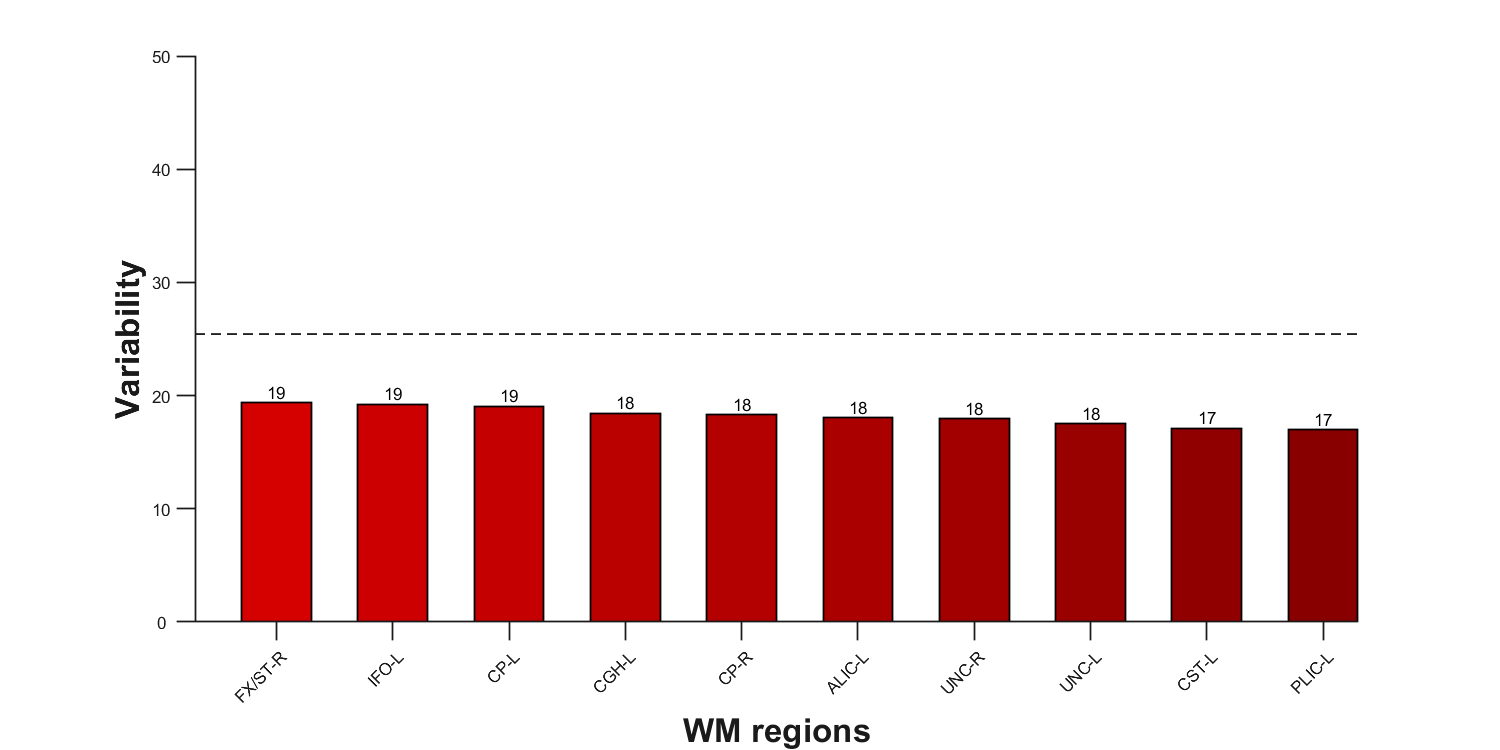

idx_bottom_n=idx_sorted(51-n:50);
bottom_n=roi50_info(idx_bottom_n);
bottom_n_label=roilabel(idx_bottom_n);
% map=jet(50);
original_hot=hot(80);
map = flipud(original_hot(16:65,:));
x=1:n;

idffs=bar(x,bottom_n,'BarWidth',0.6,'EdgeColor',"k","LineWidth",1);
idffs.FaceColor='flat';
for i=1:n
%     idffs.CData(i,:)=map(idx_bottom_n(i),:);
    idffs.CData(i,:)=map(50-n+i,:);
end
% ymax=0.03;
% ytic=0.001;
ymax=50;
ytic=10;
set(gca, 'Box', 'off', ...                                       
        'LineWidth', 1, 'GridLineStyle', '-',...               
        'XGrid', 'off', 'YGrid', 'off', ...                    
        'TickDir', 'out', 'TickLength', [.015 .015], ...      
        'XMinorTick', 'off', 'YMinorTick', 'off', ...          
        'XColor', [.1 .1 .1],  'YColor',[.1 .1 .1],...           
        'YTick', 0:ytic:ymax,...                                    
        'Ylim' , [0 ymax], ...                                    
        'Xlim' , [0.3 n+0.3], ...
        'XTick', 1:1:n,...
        'Xticklabel',bottom_n_label,...                                 
        'Yticklabel',{0:ytic:ymax})                                
xtickangle(45);
xlabel('WM regions', 'FontSize', 20, 'FontWeight', 'bold');
ylabel('Variability', 'FontSize', 20, 'FontWeight', 'bold');

for i = 1:numel(bottom_n)
    text(i, bottom_n(i), num2str(bottom_n(i),'%.2g'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')
end
hold on;
    avg=mean(roi50_info);
    line(get(gca,'xlim'),[avg,avg],'Color','k','Linewidth',1,'LineStyle','--');
    hold off;

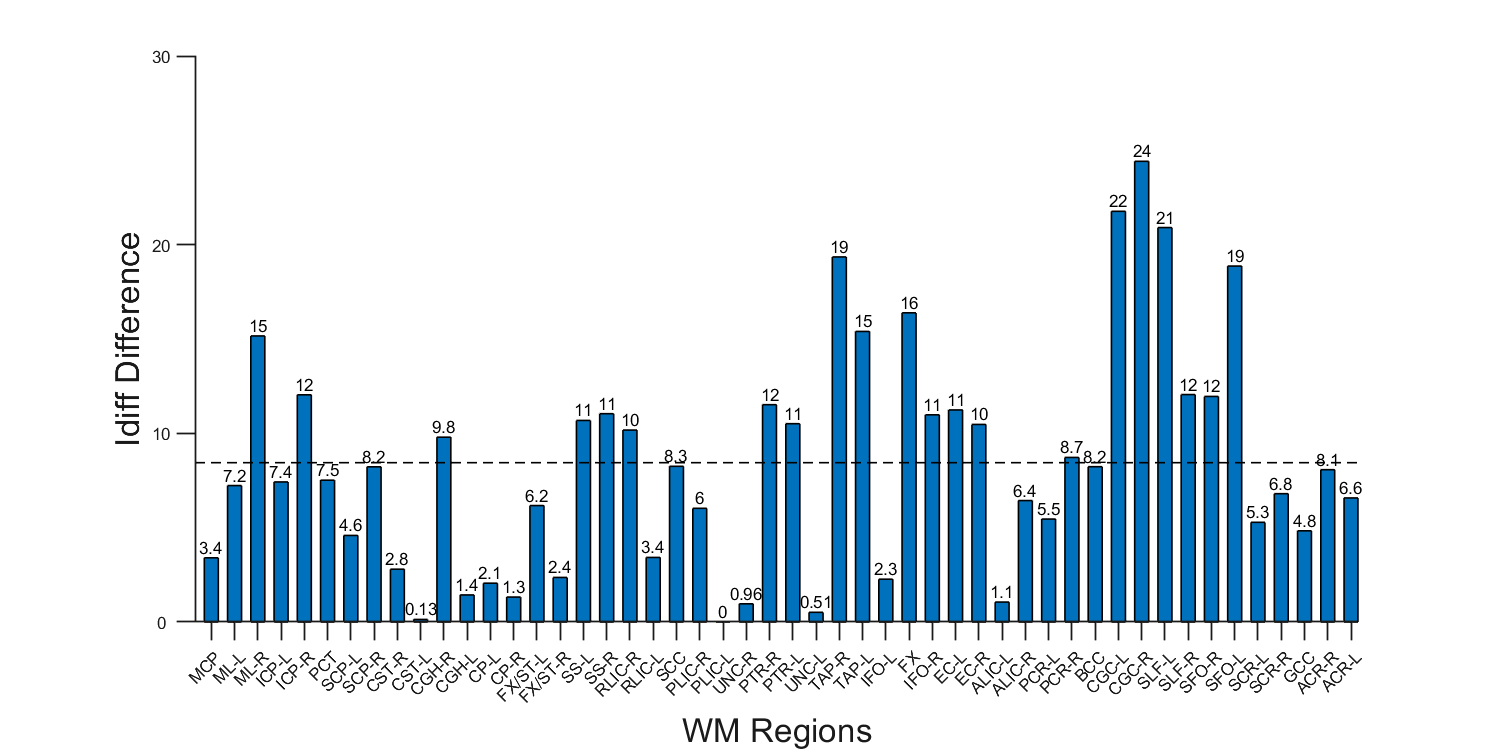


%Draw idiff change histogram (icbm) according to the descending order of brain area depth
roi50_info=load('./Experimental_Results\ICBM_DTI_81_ROIS\idiff_arr.mat').idiff_arr;
% roi50_depth=load('../WM_depth/ICBM_relative_7_depth.mat').depth;
roi50_depth=load('./WM_Relative_Distances/ICBM__relative_1_depth.mat').depth;
[idiff_v_sorted, idiff_idx_sorted] = sort(roi50_info, 'ascend');
[v_sorted, idx_sorted] = sort(roi50_depth, 'ascend');
sorted_idiff=roi50_info(idx_sorted);
sorted_idiff=sorted_idiff-min(sorted_idiff);
[idiff_v_sorted, idiff_idx_sorted] = sort(sorted_idiff, 'ascend');


roi50_wholelabel=importdata('./Experimental_Results/LabelLookupTable.txt');
roilabel=cell(1,50);
for i=1:50
    subinfo=split(roi50_wholelabel{i},'	');
    roilabel{i}=subinfo{2};
end
sorted_label=roilabel(idx_sorted);

n=50;
y_max=30;
label1='Idiff Difference';
RegionalGraident(sorted_idiff,n,y_max,sorted_label); 
ylabel('Idiff Difference',"FontSize",20);

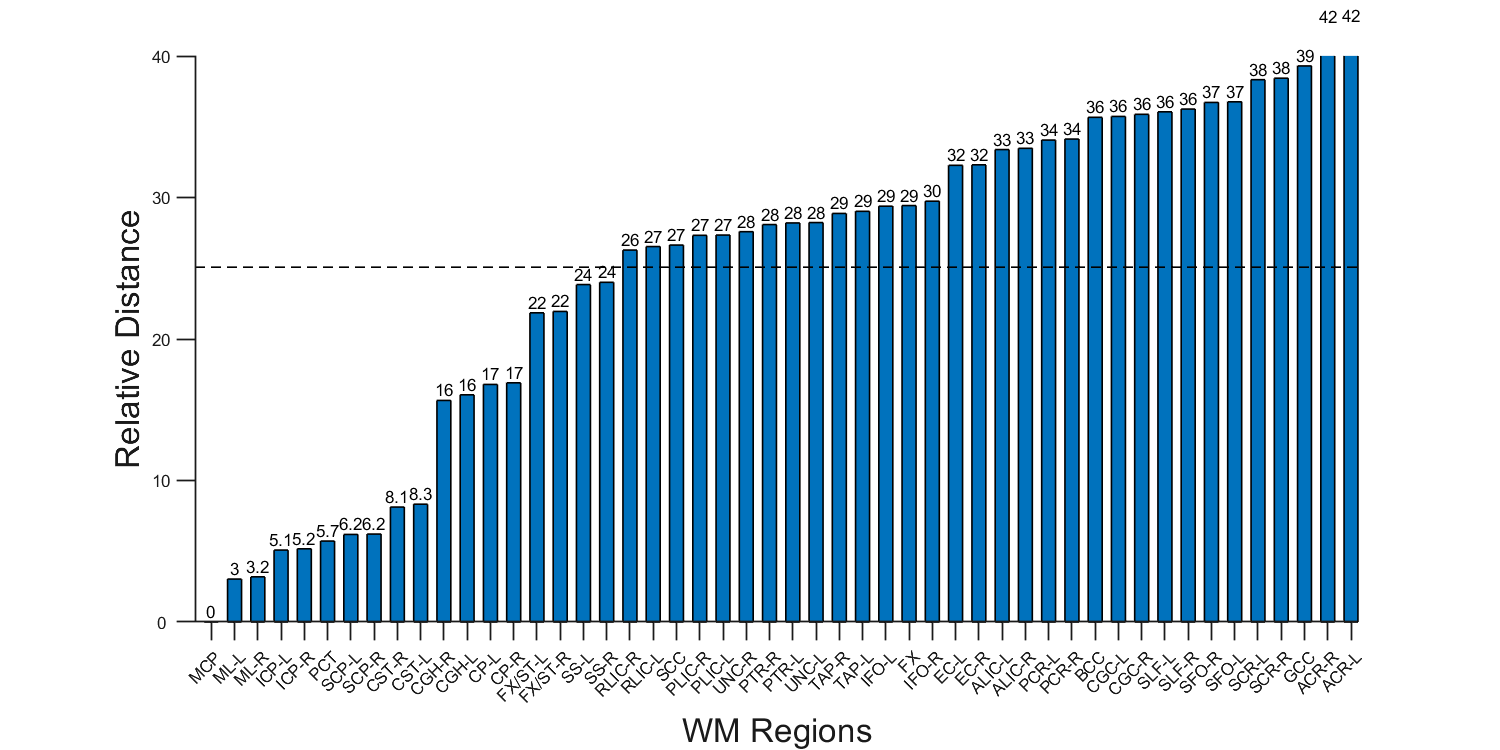


relative_distance=v_sorted;
n=50;
y_max=40;
RegionalGraident(relative_distance,n,y_max,sorted_label); 
ylabel('Relative Distance',"FontSize",20);

% Pearson correlation between Relative distances and Idiff
atlas_center_path='./Materials/rICBM_WMPM_center_coor.mat';
roi_info=load('./Experimental_Results/ICBM_DTI_81_ROIS/idiff_arr.mat').idiff_arr;
for id=1:50
depth=RelativeDepth(atlas_center_path,id);
% save_path=['../WM_depth/ICBM__relative_' num2str(id) '_depth.mat'];
% save(save_path,'depth');

roi_info=roi_info-min(roi_info);
roi_depth=load(['./WM_Relative_Distances/ICBM__relative_' num2str(id) '_depth.mat']).depth;
roi_info=reshape(roi_info,[50,1]);
[rho_pearson_alt, p_pearson_alt] = corr(roi_info, roi_depth, 'Type', 'Pearson');
fprintf('%d Pearson correlation (corr): %.4f (p=%.4g)\n', id,rho_pearson_alt, p_pearson_alt);
end

1 Pearson correlation (corr): 0.2675 (p=0.06037)
2 Pearson correlation (corr): 0.3348 (p=0.01746)
3 Pearson correlation (corr): 0.0985 (p=0.4963)
4 Pearson correlation (corr): -0.2755 (p=0.05281)
5 Pearson correlation (corr): -0.2750 (p=0.0533)
6 Pearson correlation (corr): -0.1244 (p=0.3894)
7 Pearson correlation (corr): 0.4006 (p=0.003941)
8 Pearson correlation (corr): 0.3461 (p=0.01383)
9 Pearson correlation (corr): 0.2987 (p=0.03511)
10 Pearson correlation (corr): 0.2560 (p=0.07276)
11 Pearson correlation (corr): 0.2723 (p=0.0557)
12 Pearson correlation (corr): 0.2157 (p=0.1324)
13 Pearson correlation (corr): 0.2615 (p=0.06657)
14 Pearson correlation (corr): 0.2107 (p=0.1419)
15 Pearson correlation (corr): 0.4307 (p=0.001796)
16 Pearson correlation (corr): 0.2872 (p=0.04318)
17 Pearson correlation (corr): 0.1146 (p=0.4281)
18 Pearson correlation (corr): -0.0098 (p=0.9461)
19 Pearson correlation (corr): 0.0899 (p=0.5347)
20 Pearson correlation (corr): -0.0851 (p=0.557)
21 Pearson co

% Spearman correlation between Relative distances and Idiff
for id=1:50
depth=RelativeDepth(atlas_center_path,id);
% save_path=['../WM_depth/ICBM__relative_' num2str(id) '_depth.mat'];
% save(save_path,'depth');

roi_info=roi_info-min(roi_info);
roi_depth=load(['./WM_Relative_Distances/ICBM__relative_' num2str(id) '_depth.mat']).depth;
roi_info=reshape(roi_info,[50,1]);
[rho_spearman_alt, p_spearman_alt] = corr(roi_info, roi_depth, 'Type', 'Spearman');
fprintf('%d Spearman correlation (corr): %.4f (p=%.4g)\n', id,rho_spearman_alt, p_spearman_alt);
end

1 Spearman correlation (corr): 0.2715 (p=0.05683)
2 Spearman correlation (corr): 0.3250 (p=0.0217)
3 Spearman correlation (corr): 0.1524 (p=0.2899)
4 Spearman correlation (corr): -0.1659 (p=0.2487)
5 Spearman correlation (corr): -0.3195 (p=0.02416)
6 Spearman correlation (corr): 0.0307 (p=0.8321)
7 Spearman correlation (corr): 0.4036 (p=0.003903)
8 Spearman correlation (corr): 0.3340 (p=0.0182)
9 Spearman correlation (corr): 0.3227 (p=0.02269)
10 Spearman correlation (corr): 0.2423 (p=0.09014)
11 Spearman correlation (corr): 0.2724 (p=0.05593)
12 Spearman correlation (corr): 0.1969 (p=0.17)
13 Spearman correlation (corr): 0.2599 (p=0.06853)
14 Spearman correlation (corr): 0.1915 (p=0.1824)
15 Spearman correlation (corr): 0.4836 (p=0.0004385)
16 Spearman correlation (corr): 0.2452 (p=0.08616)
17 Spearman correlation (corr): 0.2175 (p=0.129)
18 Spearman correlation (corr): 0.0219 (p=0.8796)
19 Spearman correlation (corr): 0.1946 (p=0.1751)
20 Spearman correlation (corr): -0.0842 (p=0.56)

function idiff=Idiff_cal_undigonal(mat)
%Calculate the Differential Identifiability of the similarity matrix (excluding diagonal elements)
    iself=0;
    for i=1:100
        if mod(i,10)~=0
            movsteps=i+10-mod(i,10);
        else
            movsteps=i;
        end
        
        for j=i+1:movsteps
            iself = iself+ mat(i,j);
        end
    end
    iothers=(sum(mat(:))-100)/2-iself;%without digonal elements
    iothers=iothers/4500;
    iself=iself/450;
    idiff=100*(iself-iothers);
end

function GlobalFunctionalVariability(sm)
% Visualization of global functional variability through fALFF similarity
idiff=Idiff_cal_undigonal(sm);
% min(min(sm1))
imagesc(sm);
grid on;
set(gca, 'GridColor', 'black', 'GridAlpha', 1, 'LineWidth', 1.2);
title(['fALFF Similarity Matrix  Idiff = ' num2str(idiff)],'FontSize', 16);
colorbar;
caxis([0.3,1]);
xticks(0.5:10:100.5);
yticks(0.5:10:100.5);
% axis equal;
daspect([1 1 1]);
labels=cell(1,10);
for i=1:10
    if i==6
        labels{i}='Subject scans';
    else
        labels{i}='';
    end   
end

xticklabels(labels);
set(gca, 'FontSize', 16);
yticklabels(labels);
ytickangle(90);
end


function RegionalGraident(sorted_idiff,n,y_max,sorted_label)
% Visualization of idiff difference or relative distances
x=1:n;
figure('Position',[100,100,1200,600])
idffs=bar(x,sorted_idiff,'BarWidth',0.6,'EdgeColor',"k","LineWidth",1,"FaceColor","flat");
% idffs.FaceColor='flat';
xlabel('WM Regions',"FontSize",20);
% ylabel(ylabel,"FontSize",20);
set(gca, 'Box', 'off', ...                                        
        'LineWidth', 1, 'GridLineStyle', '-',...                  
        'XGrid', 'off', 'YGrid', 'off', ...                       
        'TickDir', 'out', 'TickLength', [.015 .015], ...          
        'XMinorTick', 'off', 'YMinorTick', 'off', ...             
        'XColor', [.1 .1 .1],  'YColor',[.1 .1 .1],...            
        'YTick', 0:10:y_max,...                                      
        'Ylim' , [0 y_max], ...                                    
        'Xlim' , [0.3 n+0.3], ...
        'XTick', 1:1:n,...
        'Xticklabel',sorted_label,...                                  
        'Yticklabel',{0:10:50})                                 
xtickangle(45);
for i = 1:numel(sorted_idiff)
    text(i, sorted_idiff(i), num2str(sorted_idiff(i),'%.2g'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')
end
hold on;
    avg=mean(sorted_idiff);
    line(get(gca,'xlim'),[avg,avg],'Color','k','Linewidth',1,'LineStyle','--');
    hold off;
end

function distances=RelativeDepth(atlas_center_path,basic_roi)
%     Compute all the relative distances to reference regions
    coords=load(atlas_center_path).center_coordinates;
    ref_coord = coords(basic_roi, :);
    distances = sqrt(sum((coords - ref_coord).^2, 2));
end